**Task 1** - Use Matlab’s neural network tool box to create a 3 class decision classifier for the 3 class data generated in Exercise 1.

K = 1000;
D = 3;

% Dataset A
mu_A = [0 4 7];
sigma_A = [6.5000 2.1651 1.2500 ; 2.1651 5.1250 2.3816;1.2500 2.3816 2.3750];
data_A = gaussian_data_from_ss(K,D,mu_A,sigma_A);

% Dataset B
mu_B = [10 5 5];
sigma_B = [3.0184 0.4331 -1.4481; 0.4331 0.9436 -0.6456 ;-1.4481 -0.6456 1.2880];
data_B = gaussian_data_from_ss(K,D,mu_B,sigma_B);

% Dataset C
mu_C = [-2 -5 -5];
sigma_C = [6.8928 -1.3750 3.1945 ;-1.3750 3.3572 0.6945;3.1945 0.6945 3.7500];
data_C = gaussian_data_from_ss(K,D,mu_C,sigma_C);

input_data = [data_A; data_B; data_C];

target = [1*ones(K,1); 2*ones(K,1); 3*ones(K,1)];
target_new = bsxfun(@eq, target(:), 1:max(target));

Vaxis = [-15 20 -15 20 -15 20];
volume = vol3D(Vaxis, 75);

NN_Classification_T1  = nprtool_fun(input_data, target_new, volume)

NN_Classification_T1 =      3
     3
     3
     3
     3
     3
     3
     3
     3
     3


ans =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


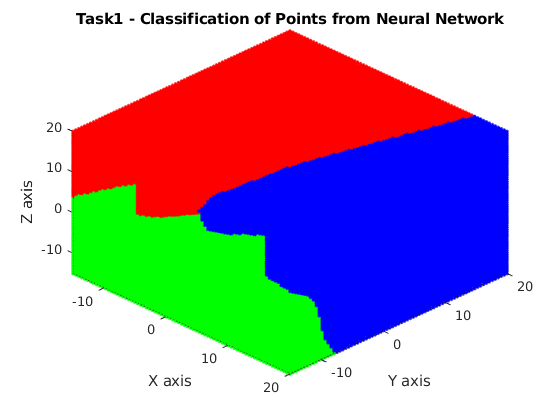

figure(1)
vis_pts_T1 = visualize_points(NN_Classification_T1,volume);
title('Task1 - Classification of Points from Neural Network')

**Task 2** - Plot the decision boundaries created by this trained neural network classifier and discuss the ”correctness” of these boundaries versus the Bayesian class boundaries that were generated in Exercise 1. 

Solution: 

figure(2);
change_val  = [0; diff(NN_Classification_T1)] % Finds points where classification of points in volume changes

change_val =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


b = volume(change_val~= 0,:) % Subset of volume where points change (describes the decision boundary)

b =   -15.0000  -15.0000    3.9189
  -15.0000  -14.5270  -15.0000
  -15.0000  -14.5270    3.9189
  -15.0000  -14.0541  -15.0000
  -15.0000  -14.0541    3.9189
  -15.0000  -13.5811  -15.0000
  -15.0000  -13.5811    3.4459
  -15.0000  -13.1081  -15.0000
  -15.0000  -13.1081    3.4459
  -15.0000  -12.6351  -15.0000


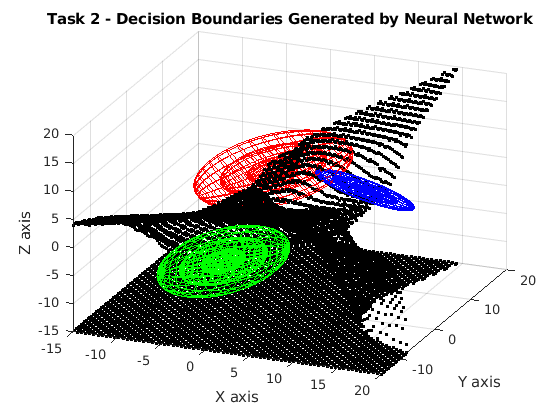

vis_boundary_T2 = visualize_boundary(data_A, data_B, data_C, b);
title('Task 2 - Decision Boundaries Generated by Neural Network')

Comments: 

correctness 

**Task 3 **- Discuss whether or not (and why) Matlab’s computation of the trained neural network’s error, as implemented within its neural net toolbox, is correct.

- Type command to see whats under the hood 

**Task 4** - Perform 10 different neural network trainings, each using different random seeds, and discuss the variability that arises in the produced interclass decision boundaries. • Discuss what would occur relative to the produced decision boundaries if 100 different neural network training were conducted. • Discuss which of the resulting neural network decision boundaries is the correct (or more correct) boundary. • Discuss how the nature of the neural network decision boundaries would change as increasingly more neurons are added to the neural network’s hidden layer(s). 

- Recreate the neural net object from scratch 10 times 

- Dont just re-train 10 times - you will get the same boundary! 

- want the different random weight settings 

**Task 5** - Discuss in detail why or why not the neural network will ever be able to produce decision boundaries equivalent to the Bayes boundaries. 

**Task 6** - Assess whether or not the neural network boundaries are more or less sensitive to outliers than the Bayesian boundaries. 2 

**Task 7** - Discuss the trade-offs that occur between generalizability and overfitting as the ratio of training data to test data is changed, i.e., for example from 90:10 to 10:90.

function f = gaussian_data_from_ss(K,D,mu,sigma)
    N = randn(K,D); % Generate a subset of K D-dimensional samples from a normal distribution
    N_c = N - mean(N); % Centralize the data at zero-mean
    
    [v,d] = eig(cov(N_c)); % Obtain eigen values and eigen vectors for covariance of N    
    R = v*inv(sqrt(d)); % Generate the whitening transform
    W  = N_c*R; % Apply the whitening transform on the centralized data
    
    [vn,dn] = eig(sigma); % Obtain eigen values and eigen vectors of the desired covariance
    R_inv = sqrt(dn)*inv(vn); % Generate the inverse whitening transform
    f = W*R_inv; % Apply the inverse whitening transfrom on the whitened gaussian data 
    f = f + mu; % Centralize the data at the desired mu
end 


function NN_classification = nprtool_fun(input_data, target_data, testing_data)
% NPRTOOL generated script 
x = input_data';
t = target_data';

% Choose a Training Function
% For a list of all training functions type: help nntrain
% 'trainlm' is usually fastest.
% 'trainbr' takes longer but may be better for challenging problems.
% 'trainscg' uses less memory. Suitable in low memory situations.
trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.

% Create a Pattern Recognition Network
hiddenLayerSize = 10;
net = patternnet(hiddenLayerSize, trainFcn);

% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;

% Train the Network
[net,tr] = train(net,x,t);

% % Test the Network
% y = net(x);
% e = gsubtract(t,y);
% performance = perform(net,t,y)
% tind = vec2ind(t);
% yind = vec2ind(y);
% percentErrors = sum(tind ~= yind)/numel(tind);
% 
% % View the Network
% view(net)
% 
% % Plots
% % Uncomment these lines to enable various plots.
% %figure, plotperform(tr)
% %figure, plottrainstate(tr)
% %figure, ploterrhist(e)
% %figure, plotconfusion(t,y)
% %figure, plotroc(t,y)

%Changes made to generated script to test generated model on volume data
% Test the Network on volume data
y = net(testing_data');
yind = vec2ind(y);
NN_classification = yind';
end

function axes_plot = visualize_points(class_index,V)

    XA = V(class_index == 1,:);
    XB = V(class_index == 2,:);
    XC = V(class_index == 3,:);
    
    axes_plot = axes;
    hold(axes_plot,'on');
    plot3(XA(:,1),XA(:,2),XA(:,3),'Marker','.','LineStyle','none','Color','r');
    plot3(XB(:,1),XB(:,2),XB(:,3),'Marker','.','LineStyle','none','Color','b');
    plot3(XC(:,1),XC(:,2),XC(:,3),'Marker','.','LineStyle','none','Color','g');
    
    xlabel('X axis');
    ylabel('Y axis');
    zlabel('Z axis');
    
    xlim(axes_plot,[-15 20]);
    ylim(axes_plot,[-15 20]);
    zlim(axes_plot,[-15 20]);
    view(axes_plot,[45 45]);
    grid(axes_plot,'on');
    hold(axes_plot,'off');
end


function [x1,y1,z1,x2,y2,z2,x3,y3,z3] = ellipse_cord(data)

    mu = mean(data);
    sigma = cov(data);
    [v,d] = eig(sigma);
    %plot ellipsoid for three standard deviations
    radius = sqrt(diag(d));
    [x1,y1,z1] = ellipsoid(0, 0, 0, radius(1),radius(2),radius(3));
    [x2,y2,z2] = ellipsoid(0, 0, 0, 2*radius(1),2*radius(2),2*radius(3));
    [x3,y3,z3] = ellipsoid(0, 0, 0, 3*radius(1),3*radius(2),3*radius(3));
    

    x1 = kron(v(:,1),x1);y1 = kron(v(:,2),y1);z1 = kron(v(:,3),z1);
    x2 = kron(v(:,1),x2);y2 = kron(v(:,2),y2);z2 = kron(v(:,3),z2);
    x3 = kron(v(:,1),x3);y3 = kron(v(:,2),y3);z3 = kron(v(:,3),z3);
    dat1 = x1 + y1 + z1; dat2 = x2 + y2 + z2 ; dat3 = x3 + y3 + z3; % to account for rotation of all three axis 
    n = size(dat1,2);
    x1 = dat1(1:n,:) + mu(1); y1 = dat1(n+1:2*n,:) + mu(2); z1 = dat1(2*n+1:end,:) + mu(3); 
    x2 = dat2(1:n,:) + mu(1); y2 = dat2(n+1:2*n,:) + mu(2); z2 = dat2(2*n+1:end,:) + mu(3);
    x3 = dat3(1:n,:) + mu(1); y3 = dat3(n+1:2*n,:) + mu(2); z3 = dat3(2*n+1:end,:) + mu(3); 
end 

function val = gaussian_density(mu,sigma,X)
%finds the gaussian pdf 
    [k,d] = size(X);
    X0 = bsxfun(@minus,X,mu);
    [R,err] = cholcov(sigma,0);
    xRinv = X0 / R;
    % determinant of sigma is product of diagonal elements of cholesky decomposition
    logSqrtDetSigma = sum(log(diag(R))); 
    quadratic = sum(xRinv.^2, 2);
    val = exp(-0.5*quadratic - logSqrtDetSigma - d*log(2*pi)/2);
end 

function axes_plot = visualize_boundary(data_A, data_B, data_C, b)

    mu_A = mean(data_A);
    mu_B = mean(data_B);
    mu_C = mean(data_C);

    sigma_A = cov(data_A);
    sigma_B = cov(data_B);
    sigma_C = cov(data_C);

    [vA,dA] = eig(sigma_A);
    [vB,dB] = eig(sigma_B);
    [vC,dC] = eig(sigma_C);

    axes_plot = axes;
    hold(axes_plot,'on');
    [xA1,yA1,zA1,xA2,yA2,zA2,xA3,yA3,zA3] = ellipse_cord(data_A);
    surf(xA1, yA1, zA1,'EdgeColor', 'r','FaceAlpha',0);
    surf(xA2, yA2, zA2, 'EdgeColor', 'r','FaceAlpha',0);
    surf(xA3, yA3, zA3,'EdgeColor', 'r','FaceAlpha',0);
    [xB1,yB1,zB1,xB2,yB2,zB2,xB3,yB3,zB3] = ellipse_cord(data_B);
    surf(xB1, yB1, zB1,'EdgeColor', 'b','FaceAlpha',0);
    surf(xB2, yB2, zB2, 'EdgeColor', 'b','FaceAlpha',0);
    surf(xB3, yB3, zB3,'EdgeColor', 'b','FaceAlpha',0);
    [xC1,yC1,zC1,xC2,yC2,zC2,xC3,yC3,zC3] = ellipse_cord(data_C);
    surf(xC1, yC1, zC1,'EdgeColor', 'g','FaceAlpha',0);
    surf(xC2, yC2, zC2, 'EdgeColor', 'g','FaceAlpha',0);
    surf(xC3, yC3, zC3,'EdgeColor', 'g','FaceAlpha',0);

    %plot decision boundaries
    plot3(b(:,1),b(:,2),b(:,3),'Marker','.','LineStyle','none','Color','k');
    % Create zlabel
    zlabel('Z axis');

    % Create ylabel
    ylabel('Y axis');

    % Create xlabel
    xlabel('X axis');

    % Create title

    xlim(axes_plot,[-15 20]);
    ylim(axes_plot,[-15 20]);
    zlim(axes_plot,[-15 20]);
    view(axes_plot,[45 45]);
    grid(axes_plot,'on');
    hold(axes_plot,'off');
end


function V = vol3D(Vaxis,Num) 
    NV = Num;
    
    if length(Vaxis) == 2
        Vaxis = [Vaxis Vaxis Vaxis];
    end
    
    min_a = Vaxis(1);
    max_a = Vaxis(2);
    res = (max_a-min_a)/(NV-1);
    
    r = min_a:res:max_a;
    r = r(:);
    
    rx = [Vaxis(1):(Vaxis(2)-Vaxis(1))/(NV-1):Vaxis(2)]';
    ry = [Vaxis(3):(Vaxis(4)-Vaxis(3))/(NV-1):Vaxis(4)]';
    rz = [Vaxis(5):(Vaxis(6)-Vaxis(5))/(NV-1):Vaxis(6)]';
    
    x = zeros(3,length(rz)^3);
    k =1;
    j = 1;
    for i = 1:length(rz):length(x)
        x(3,(i-1)+(1:length(rz)))= rz;
        x(2,(i-1)+(1:length(rz))) = ry(k)*ones(1,length(rz));
        x(1,(i-1)+(1:length(rz))) = rx(j)*ones(1,length(rz));
        k = k+1;
        if k > length(rz)
            k =1;
            j = j +1;
        end
    end
    x = x';
    V = x;

end